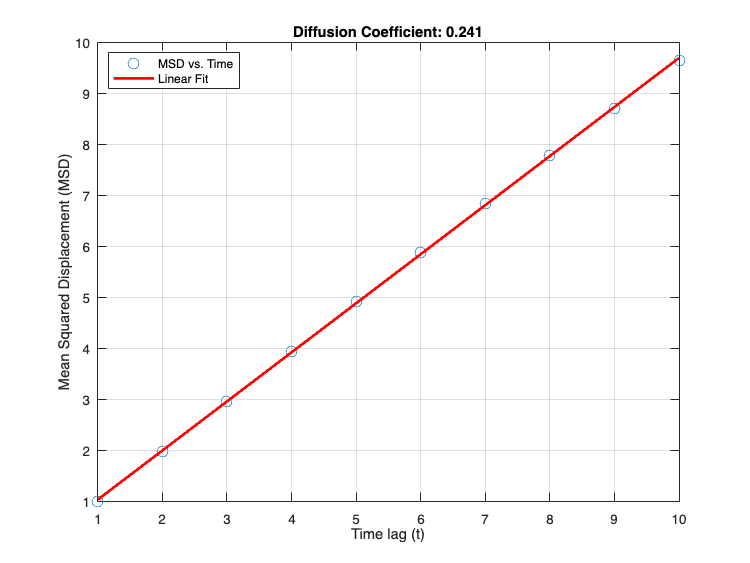

%simulate and analyze 2D random walk

%set parameters for 1 particle over 5000 steps
numParticles = 1;
numSteps = 5000;

%initialize position arrays for x and y
x = zeros(numParticles, numSteps);
y = zeros(numParticles, numSteps);

%simulate 2D random walk
for stepNumber = 2 : numSteps
    for p = 1 : numParticles
        %take random steps in x and y directions
        xStep = 1 * sign(randn());
        yStep = 1 * sign(randn());
        %update positions
        x(p, stepNumber) = x(p, stepNumber - 1) + xStep;
        y(p, stepNumber) = y(p, stepNumber - 1) + yStep;
    end
end

%combine x and y into one array
track_2D = [x; y];

%use this track for MSD calculation
track = track_2D;

%define time lags
lags = 1:10;

%initialize MSD array
msd = zeros(1, length(lags));

%compute MSD for each lag
for lag = lags
    displacements = track(:, lag+1:end) - track(:, 1:end-lag); %Δx and Δy
    squared_displacements = displacements.^2; %(Δx)^2 + (Δy)^2
    msd(lag) = mean(squared_displacements(:));%average over all
end

%fit MSD vs. lag linearly to get diffusion coefficient (MSD = 4Dt in 2D)
fit_result = polyfit(lags, msd, 1);
diff_coefficient = fit_result(1) / 4;

%plot MSD and linear fit
figure;
plot(lags, msd, 'o', 'MarkerSize', 8); %data points
hold on;
plot(lags, polyval(fit_result, lags), 'r-', 'LineWidth', 2); % fitted line
xlabel('Time lag (t)');
ylabel('Mean Squared Displacement (MSD)');
legend('MSD vs. Time', 'Linear Fit', 'Location', 'northwest');
title(['Diffusion Coefficient: ' num2str(diff_coefficient,3)]);
grid on;